clear;

a1=load('0.015_2.mat');
% a2=load('0.015_2.mat');
% a3=load('0.015_3.mat');
b1=load('0.025_1.mat');
% b2=load('0.025_2.mat');
% b3=load('0.025_3.mat');
c1=load('0.02_1.mat');


r=a1.rF_0.signals.values;
y=a1.theta_0.signals.values;
t=a1.u_0.time;
dt=t(2)-t(1);
data=iddata(y,r,dt);
sys=tfest(data,2,0);

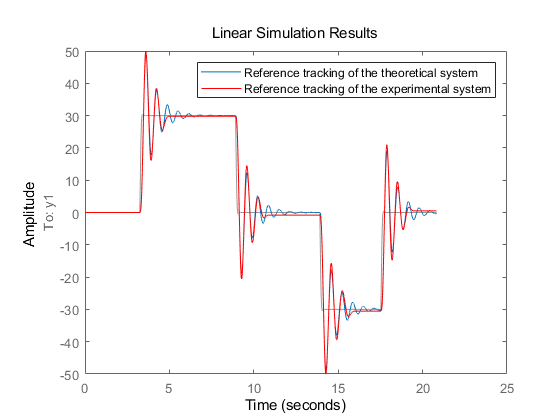

taup=1/sys.Denominator(2);
kp=sys.Denominator(3)*taup/0.015;
t1=tf([3460],[0.3707 1 0]);
figure()
hold on
lsim(sys,r,t)
plot(t,y,'r','linewidth',0.5)
legend('Reference tracking of the theoretical system', ...
       'Reference tracking of the experimental system');
ylim([-50,50])
hold off

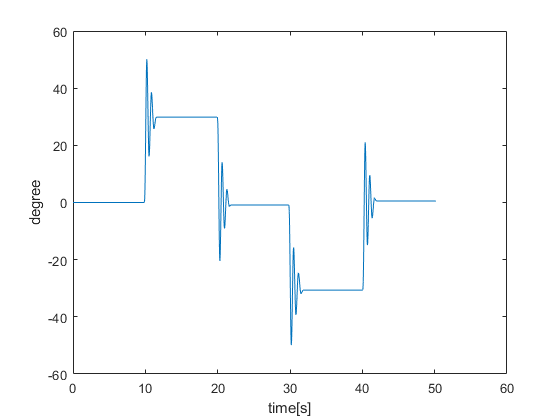


% figure()
% plot(a1.r_0.time,a1.r_0.signals.values)
% xlabel('time[s]'); ylabel('degree');
% figure()
% plot(a1.rF_0.time,a1.rF_0.signals.values)
% xlabel('time[s]'); ylabel('degree');
figure()
plot(a1.theta_0.time,a1.theta_0.signals.values)
xlabel('time[s]'); ylabel('degree');

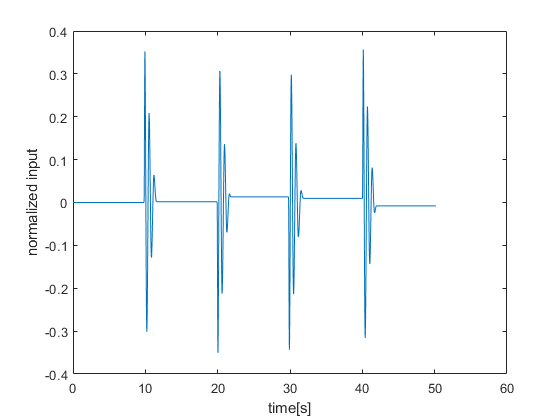

figure()
plot(a1.u_0.time,a1.u_0.signals.values)
xlabel('time[s]'); ylabel('normalized input');

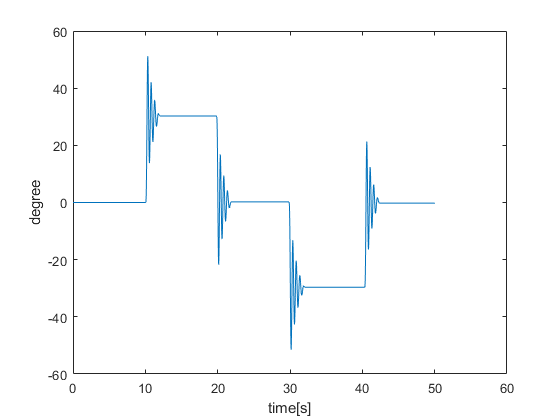


% figure()
% plot(b1.r_0.time,b1.r_0.signals.values)
% xlabel('time[s]'); ylabel('degree');
% figure()
% plot(b1.rF_0.time,b1.rF_0.signals.values)
% xlabel('time[s]'); ylabel('degree');
figure()
plot(b1.theta_0.time,b1.theta_0.signals.values)
xlabel('time[s]'); ylabel('degree');

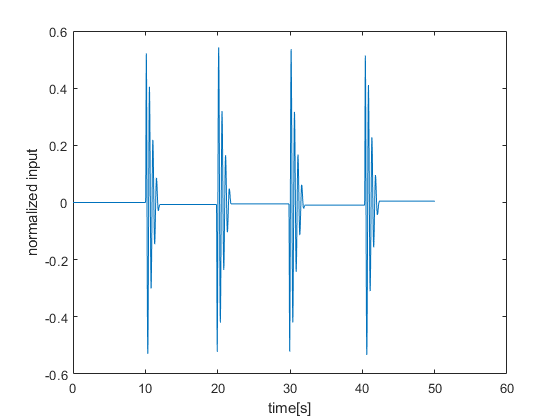

figure()
plot(b1.u_0.time,b1.u_0.signals.values)
xlabel('time[s]'); ylabel('normalized input');

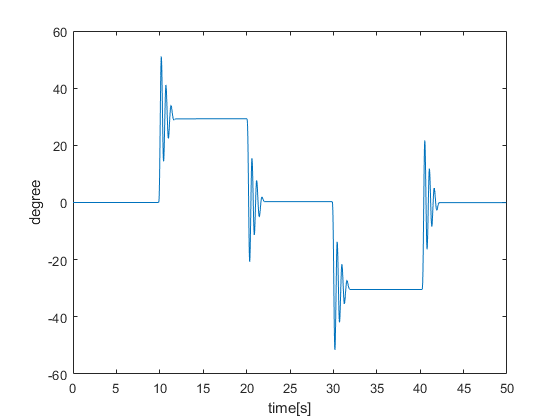

% 
% figure()
% plot(c1.r_0.time,c1.r_0.signals.values)
% xlabel('time[s]'); ylabel('degree');
% figure()
% plot(c1.rF_0.time,c1.rF_0.signals.values)
% xlabel('time[s]'); ylabel('degree');
figure()
plot(c1.theta_0.time,c1.theta_0.signals.values)
xlabel('time[s]'); ylabel('degree');

% figure()
% plot(c1.u_0.time,c1.u_0.signals.values)
% xlabel('time[s]'); ylabel('normalized input');